# LAB 3: STEP RESPONSE IDENTIFICATION OF QNET DC MOTOR

%---------------------------------------
% Fill in your group number.
GroupNumber = 29;
% Fill in your student Name and ID.
Students(1).Name = 'Ahmed Said';
Students(1).ID = '260665291';
Students(2).Name = 'Patrick Erath';
Students(2).ID = '260719203';
%---------------------------------------

## **0. Objectives**

In this lab, we will identify the transfer function of the QNET Allied Motion CL40 Series Coreless DC Motor (model 16705). We will use `MATLAB` to interact with the DC Motor in order to generate inputs/outputs data. We will then use this data to identify the model parameters of the DC motor using the properties of its time response.

## **1. A Model for DC Motor**

A DC motor is a device that converts armature current into mechanical torque. A schematic of a DC motor is shown below.

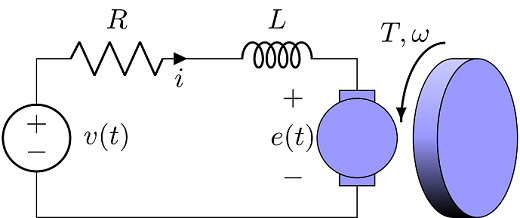

Voltage $v$ is the input to the system and the angular velocity $\omega$ of the shaft is the output. The transfer function between the input and the output may be approximated as a first order system with parameters $K$ and $\tau$ as follows.


$$ \displaystyle \frac{\Omega(s) }{ V(s) } =  \displaystyle \frac{ K }{
\tau s + 1 } $$


where

- $K$ is the `DC gain`, also called `steady state gain`. The `DC gain` represent the amplitude ratio between the steady state step response and the step input.

- $\tau$ is is the `time constant`. The `time constant` might be regarded as the time for the system's step response to reach $1-e^{-1} \approx 63.2$ % of its final value.

For a generic first order system, the parameters $K$ and $\tau$ can be extracted from the plot of the system step response (which is the response of the system to a step input):

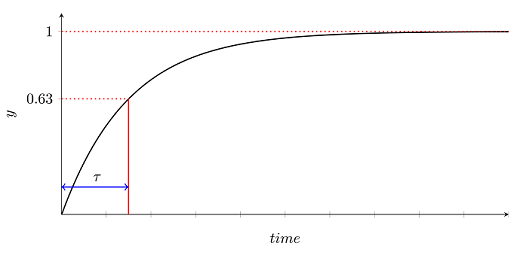

## **2. Qnet DC Motor**

## *2.1. Setting-up Qnet DC Motor*

There is a document `QNET DC Motor Quick Start Guide.pdf` on myCourse that explains how to set up the Qnet DC Motor. Carefullly follows steps 1, 2 and 4 of the guide to setup the motor.

## *2.2. Interfacing with Qnet DC Motor*

We provide a `MATLAB` interface to interact with the Qnet DC Motor. Download the file `QnetDCMotor.m` from myCourses and put it in the same folder as this liveScript.

In order to start a new communication session from `MATLAB` to the Qnet DC Motor you should run

Motor = QnetDCMotor();

QnetDCMotor::Constructor::Error:: Qnet DC Motor is not connected or already in use.
 * Make sure Qnet DC Motor is connected via the USB port.
 * Make sure you are using a valid device ID, use <help QnetDCMotor.DevicePort> for more information.
 * If you are using Qnet DC Motor in another script, clear the motor object, then call <daq.reset>.
 * If you are using Qnet DC Motor in an external program exit that program.
 If nothing works restart MATLAB!


Error using QnetDCMotor (line 159)
The device 'Dev1' is unknown. Valid device IDs are 'Dev2'.

After a successful connection you might see this warning, which you can ignore:

"Warning: On this platform, notifications more frequent than 20 times per second may not be achievable."

If `QnetDCMotor.m` fails to connect to the DC Motor an error is shown. Follow the suggestions to solve the problem or ask the TA for help.

Upon successful connection, the Qnet DC Motor status LED changes color from red to green. This means that motor is on. You can turn off, turn on, or reset (turn off, then on) the motor by running:

Motor.off(); % Set the power to off
Motor.on(); % Set the power to on
Motor.reset(); % Reset the power to off and then on. Also reset the internal timer

To send a voltage to the QnetDC Motor call the function `Motor.input(...)`. The argument of `input` function specifies the armature voltage (in volts) to be applied. This voltage is applied continuously until another input is sent.

To sync with internal DC Motor timer call the function `Motor.wait(...)`. The argument of the `wait` function specifies the time (in seconds) and blocks `MATLAB` until the internal timer of the motor reaches that time.

For example the following code waits for one second and then applies a voltage of 2V for a duration of 5 seconds.

% Value of the voltage to be applied (in V)
voltage = 2;
% Start time (in seconds) for applying the voltage
startTime = 1;
% Duration (in seconds) for which the voltage is applied
duration = 5;

% Reset the motor power and timer
Motor.reset();
% Wait for starting time
Motor.wait(startTime);
% Drive Motor with the specified voltage
Motor.input(voltage);
% Wait for the specified duration
Motor.wait(startTime+duration);
% Stop the motor
Motor.off();

Notice that we first call `Motor.reset()`. Calling `Motor.reset()` turns off the motor, then turns it on and also resets the internal clock of the motor. It is necessary to call `Motor.off()`; otherwise the motor continues to receive the last voltage. If you need to force stop the motor, first type `Ctrl-C` and then run `Motor.off()`.

After running the motor, the output may be accessed using the following four arrays:

- `Motor.time` which stores the time history

- `Motor.current` which stores the history of the armature current in ampere.

- `Motor.velocity` which stores the history of the DC motor angular velocity in radian per second.

- `Motor.angle` which stores the history of the DC motor angle in radian.

For example, we can get the resulting angular velocity from the previous input command and plot it by doing:

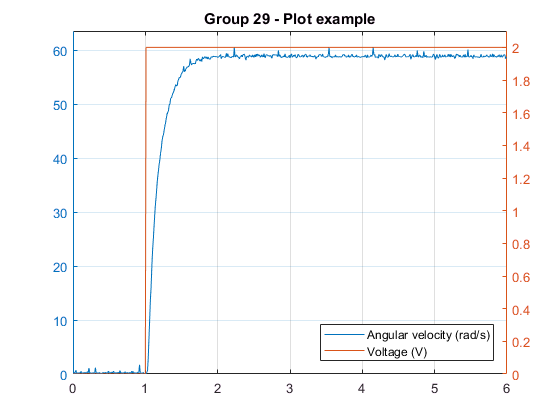

t = Motor.time;
w = Motor.velocity;
v = Motor.voltage;

figure; clf;
yyaxis left
plot(t, w)
ylim([0, 1.05 * max(w)])
yyaxis right
plot(t, v)
ylim([0, 1.05 * max(v)])
xlim([0, startTime + duration])
legend(['Angular velocity (', Motor.Units, '/s)'], 'Voltage (V)', ...
    'location', 'southeast');
title(sprintf('Group %d - Plot example', GroupNumber));
grid on

You can access detailed documentation of `QnetDCMotor.m` at anytime by using `help`:

help QnetDCMotor

 QnetDCMotor Interface for Qnet DC Motor.
    This class implements an interface to QNET Allied Motion CL40
    Series Coreless DC Motor (model 16705). The motor is driven through
    an analogue input (voltage). The motor is equipped with three
    sensors: current (A), angular velocity tachometer (units/s) and
    angle position encoder (units).
    * Syntax:
        Motor = QnetDCMotor(); % Initialize a connection with Motor   .
        Motor = QnetDCMotor('Port', 'Dev1'); % Same but Use port 'dev1'
 
    * Functions:                                                      .
        Motor.off();       % Set the power to off                     .
        Motor.on();        % Set the power to on                      .
        Motor.reset();     % Reset the power to off then on           .
        Motor.input(v);    % Send the voltage v                       .
        Motor.input(v, t); % Send the voltage v at time t             .
       

## *2.3. Saving data*

The data generated by the motor can be saved using `Motor.save(...)`. The `save(...)` function takes two arguments: the `Students` structure (that is filled in the beginning of the lab), and a tag to identify data.

For example, to save the data from the last experiment with the tag 'Lab03_example', use:

Motor.save(Students, 'Lab03_example');

Error using save
Unable to write file dataQnetMotor: permission denied.

Error in QnetDCMotor/save (line 480)
                eval(['save(filename, ''', tag, ''');']);

The data is saved in a `MAT`-file. In most hardware labs, you will be required to submit the `MAT` file along with the final LiveScript and the PDF report.

## *2.4. Loading data*

The `Motor.load(...)` function loads the data saved in the `MAT`-file. This is useful if your work is lost or corrupted. You can simply load the saved data rather than repeating the experiment. The `load` function takes 1 arguments which is the tag of the data.

For example, we can load pnd plot the reviously saved data by:

Motor.load('Lab03_example');

t = Motor.time;
w = Motor.velocity;
v = Motor.voltage;

figure; clf;
yyaxis left
plot(t, w)
ylim([0, 1.05 * max(w)])
yyaxis right
plot(t, v)
ylim([0, 1.05 * max(v)])
xlim([0, startTime + duration])
legend(['Angular velocity (', Motor.Units, '/s)'], 'Voltage (V)', ...
    'location', 'southeast');
title(sprintf('Group %d - Plot example', GroupNumber));
grid on

## **3. Data Collection: Determining Step Response**

The purpose of this experiment is to obtain the step response of the Qnet DC Motor. For this we will send a fixed voltage signal $V_{in} = 6$ volts and measure the angular velocity $\Omega$.

However, because of static friction, the transfer function between voltage and angular velocity is non linear at small voltages. To avoid this problem, we will apply a constant reference voltage of $V_{ref} = 4$ volts, before collecting the step input response.

## *Question 1 (2 marks)*

Complete the code below to apply a reference voltage of 4V for 5 seconds followed by an additional voltage of 6V for 5 seconds.

Vref = 4; % Reference signal
Tref = 5; % Duration of reference signal
Vin = 6; % Input signal
Tin = 5; % Duration of input signal


Motor.reset();
% Write the first input command here
Motor.input(Vref);
Motor.wait(Tref);
% Write the second input command here
Motor.input(Vin);
Motor.wait(Tref+Tin);

Motor.off();

Motor.save(Students, 'Lab03.Q1');

Error using save
Unable to write file dataQnetMotor: permission denied.

Error in QnetDCMotor/save (line 480)
                eval(['save(filename, ''', tag, ''');']);

## *Question 2 (1 mark)*

Complete the code below to plot your data

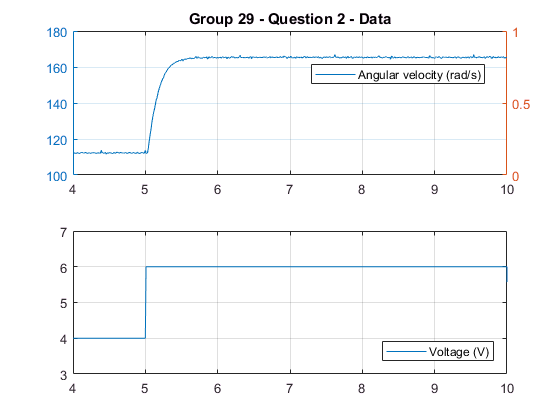

t = Motor.time;
w = Motor.velocity;
v = Motor.voltage;


figure; clf;
subplot(2, 1, 1);
% [Answer here] plot angular velocity (w) vs time (t)
yyaxis left
plot(t,w)

ylim([100, 180])
xlim([Tref - 1, Tref + Tin])
legend(['Angular velocity (', Motor.Units, '/s)'], 'location', 'best');
title(sprintf('Group %d - Question 2 - Data', GroupNumber));
grid on
subplot(2, 1, 2)
% [Answer here] plot voltage (v) vs time (t)
plot(t,v)

ylim([3, 7])
xlim([Tref - 1, Tref + Tin])
legend('Voltage (V)', 'location', 'southeast');
grid on

## **2. System identification**

## *2.1. Data analysis*

In this section, we will use the step response obtained in `Question 2` to deduce the DC gain $K$ and the time constant $\tau$. Note that the values shown in a figure can be read by opening the figure and hovering the mouse at top of the line plot.

Observe that the measurement of the angular velocity is noisy. The noise can be reduced by taking the approximate average value rather than the exact value.

For example, we can get a better approximation of the reference angular velocity $\Omega_{ref}$ resulting from $V_{ref}$ by doing:

Wref = mean(w(t > Tref-1 & t < Tref)); % Compute the average value of "w" for "t" between "Tref - 1" and "Tref".

## *Question 3 (3 marks)*

From the plot in `Question 2` find the values of DC gain $K$ and time constant $\tau$.

K=(165-112)./(6-4);
tau= .14;

## *2.2. Validating identified system*

We can use `MATLAB` to validate the calculated values of the DC gain and time constant. For this we will simulate a first order system with those values and compare it to the experimental results.

## *Question 4 (1 mark)*

Define a first order transfer function with the DC gain and time constant that you have obtained (use `tf` or `zpk`)

a1=tau;
a0=1;
b0=K;

s=tf('s');

H=(b0) / ((a1*s)+a0)


H =
 
     26.5
  ----------
  0.14 s + 1
 
Continuous-time transfer function.



The following code simulates the transfer function H(s) with a 2 volts input starting at $T_{ref}$. We are using `MATLAB` function `lsim` to simulate the output of a linear system with a given input.

tSim = t(t >= Tref & t < Tref+Tin) - Tref; % create a time signal from Tref to Tref + Tin
vSim = (Vin - Vref) * ones(size(tSim)); % create a constant voltage of Vin-Vref = 2 volts
vSim(1) = 0; % the intiial state of the system is zero
wSim = Wref + lsim(H, vSim, tSim); % simulate the output of the system H

The following code shows the simulation and the experimental results on the same plot.

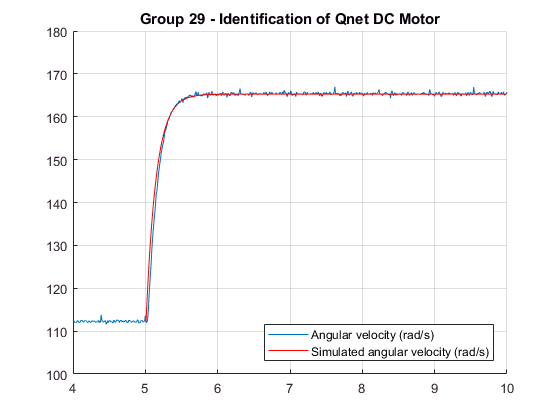

figure; clf;
hold on
plot(t, w) % experimental results
plot(tSim+Tref, wSim, 'r') % simulation of the identified transfer function
ylim([100, 180])
xlim([Tref - 1, Tref + Tin])
legend(['Angular velocity (', Motor.Units, '/s)'], ...
    ['Simulated angular velocity (', Motor.Units, '/s)'], ...
    'location', 'southeast');
title(sprintf('Group %d - Identification of Qnet DC Motor', GroupNumber));
grid on

We can measure the goodness of fit of the transfer function prediction by computing the Root-mean-square error (RMSE) between the experimental data and the predicted angular velocity with the model.


$$ RMSE = \sqrt{\displaystyle \frac{\sum_{i=1}^{n}(\omega_{Sim}(i) -
\omega_{Exp}(i))^2}{n}} $$


where $n$ is the number of elements in the angular velocity signal.

## *Question 5 (2 marks)*

- Complete the code to compute the RMSE of your fit

wExp = w(t >= Tref & t < Tref+Tin); % get the values of w between Tref and Tref + Tin
n = length(wSim)

n = 500

RMSE=sqrt(sum((wSim()-wExp()).^2)/n)

RMSE = 1.1763

- Can you tweak the values of the DC gain $K$ and time constant $\tau$ to get a better fit of the experimental data? Complete the following code to change the values of $K_{new}$ and $\tau_{new}$, re-define the transfer function $H_{new}$, re-simulate the new angular velocity, re-calculate the new RMSE, and re-plot the new fit.

KNew=26.73;
tauNew=.18;

a10=tauNew;
a00=1;
b00=KNew;
s=tf('s');

HNew= (b00)/((a10*s)+a00)


HNew =
 
    26.71
  ----------
  0.18 s + 1
 
Continuous-time transfer function.




wSimNew = Wref + lsim(HNew, vSim, tSim);

RMSENew=sqrt(sum((wSimNew()-wExp()).^2)/n)

RMSENew = 0.9952

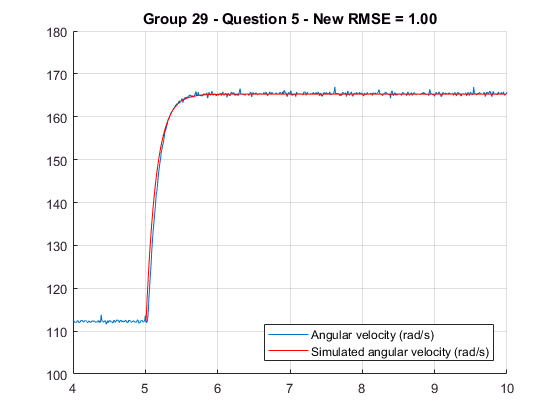



figure; clf;
hold on
plot(t, w) % experimental results
plot(tSim+Tref, wSim, 'r') % simulation of the identified transfer function
ylim([100, 180])
xlim([Tref - 1, Tref + Tin])
legend(['Angular velocity (', Motor.Units, '/s)'], ...
    ['Simulated angular velocity (', Motor.Units, '/s)'], ...
    'location', 'southeast');
title(sprintf('Group %d - Question 5 - New RMSE = %4.2f', GroupNumber, RMSENew));
grid on

## *Question 6 (1 mark)*

Another way to write the transfer function of a DC motor is as follows: $$ H(s) = \displaystyle \frac{K_t}{J R s + b R + K_t K_e} $$

Where

- $K_t$ is the torque proportionality constant in (Kg $m^2$/ $s^2$/A) or (N m/A)

- $K_e$ is the back electromotive proportionality constant in (V/rad/s)

- $R$ is the terminal resistance (Ohm)

- $J$ is the motor initia (kg $m^2$)

- $b$ is the motor viscous friction constant in (Kg $m^2$/s) or (N m s)

Suppose we know that

Kt = 0.035;
Ke = 0.035;
R = 8.4;

Using the information obtained earlier, calculate the Motor viscous friction constant $b$.

b=(1/R)*((Kt/KNew)-Kt*Ke)

b = 1.3018e-05